# Exercise 1: Getting Started: Visualize Noisy Detections 

This example uses a simple constant velocity target (simulating a plane) and simulated (noisy) radar detection data to show how we can setup a tracker and visualize how well it does in tracking the motion of the target.

The plane is assumed to be moving with constant velocity. We show the covariance around the plane as a green ellipse.  The covariance represents the confidence that we have in the detection data for the plane.

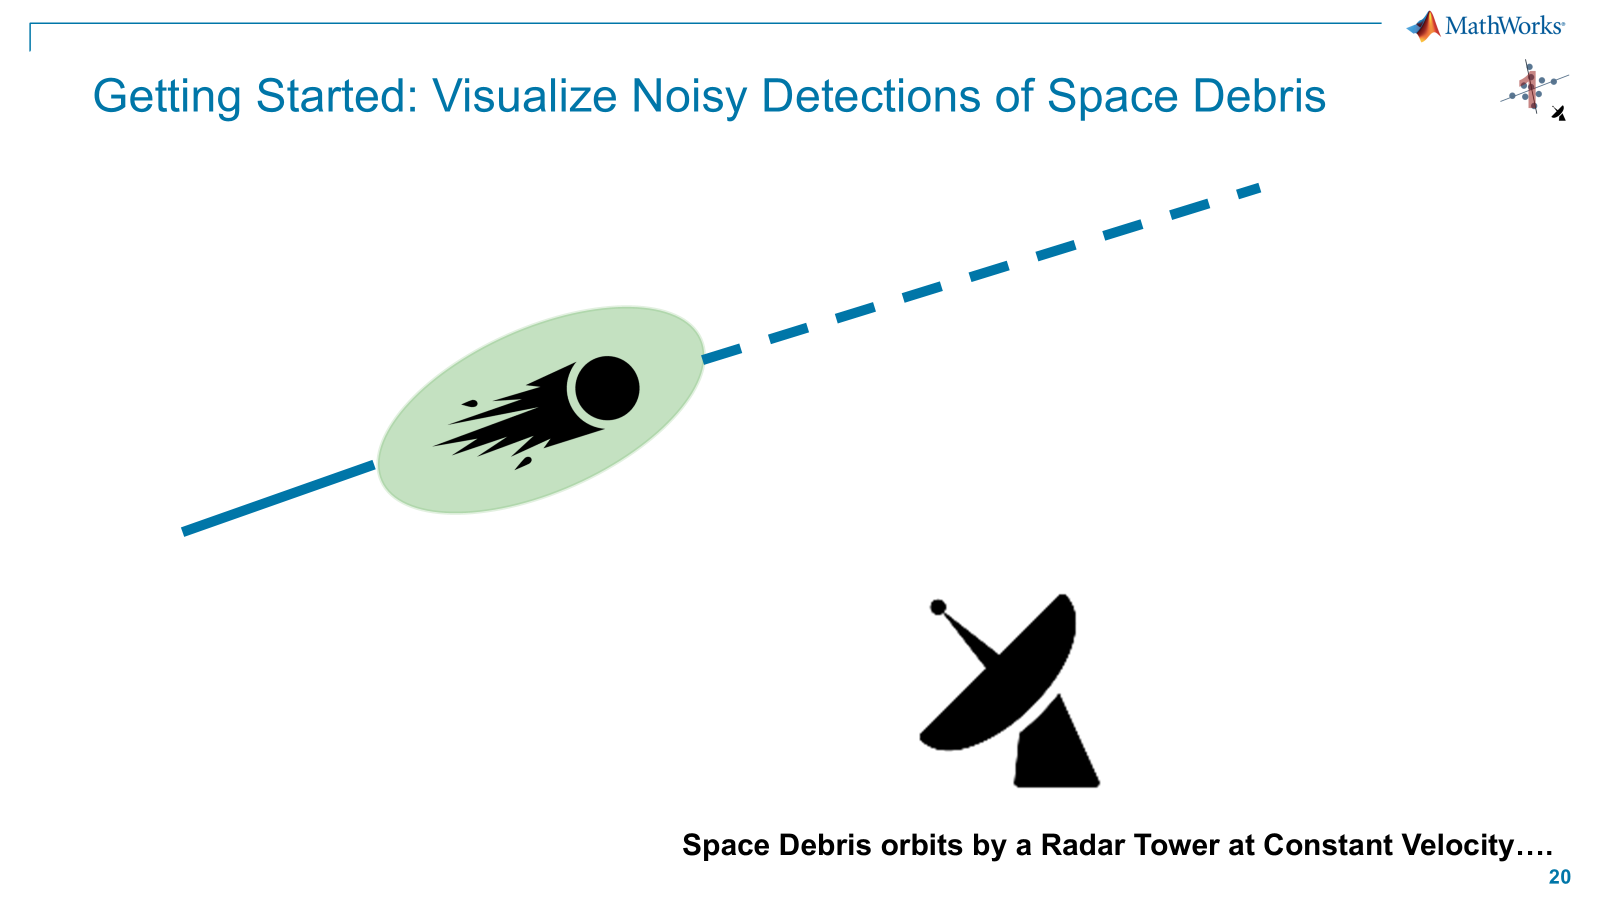

clear
clc
rng default

## Exercise 1a

For this analysis, you are given a .MAT file of truth and detection data.  Load that .MAT file here:

S = load('SpaceDebris4Targets_New.mat');
truthPos = S.truthPos; % Truth Position - where the target actually is
detPos = S.detPos;     % Detection Position - where the target was detected
time = S.time;

Before working to configure a tracker, it can be helpful to visualize your dataset. Visualize the data to get a general understanding of what we have:

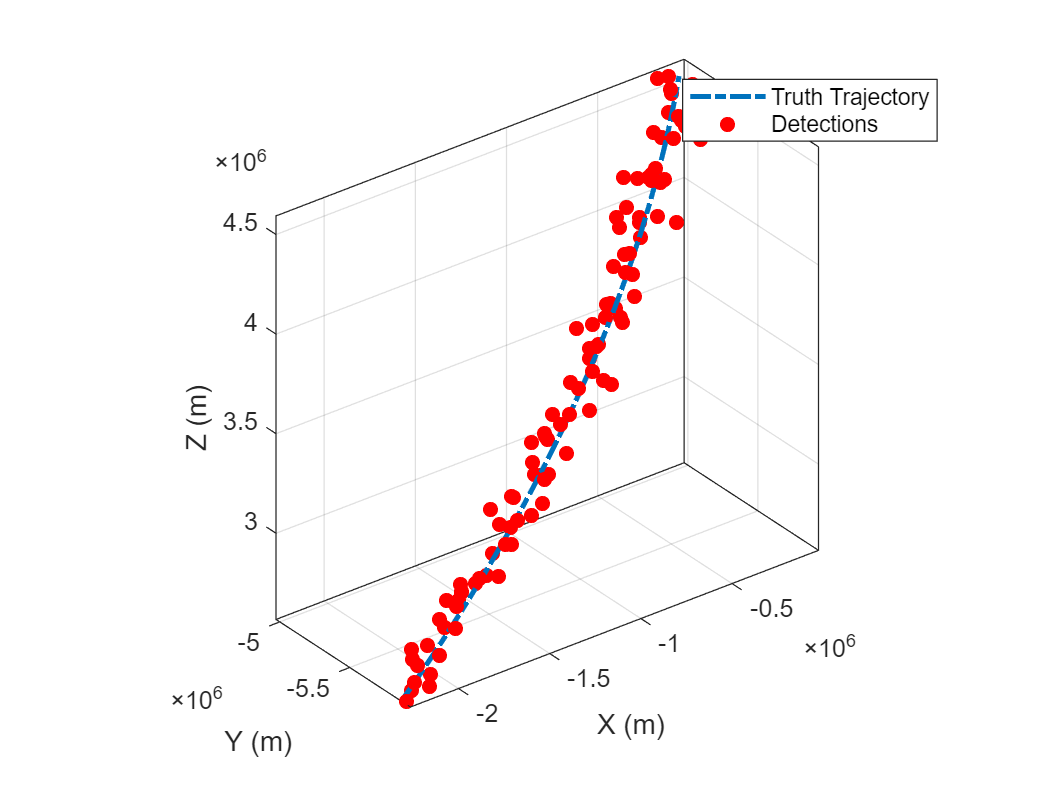

figure
ax = gca;
plot3(truthPos(1,:),truthPos(2,:),truthPos(3,:),'-.','LineWidth',2)
hold on; grid on; axis equal; box on; %zlim([0 1e4]); rotate3d on
scatter3(detPos(1,:),detPos(2,:),detPos(3,:),'filled','r')
legend({'Truth Trajectory','Detections'},'Location','northeast')
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');

%view(-18,28)

## **Exercise 1b**

Leverage the Sensor Fusion and Tracking plotter tools to visualize the truth trajectory and detections data.

### **Configure Scenario Visualization**

We have plotted the data and have an idea of what it looks like. Now, we can create a tracking scenario using that data, which will allow us to start with a relatively easy-to-use tracker and corresponding filter.  This will help us to assess whether or not our tracker meets our tracking specifications.

Create a scenario based on the Truth Data, so that we can visualize the tracker.  The plot below shows the progress of a constant velocity platform as it passes by a radar sensor mounted on a radar tower.

Directions:

Below, please create a variable 'tp' that holds a theaterplot object with default settings. 

% Setup Plotters:
figure
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% USER CODES THIS:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

The code below uses plotter objects to plot the truth trajectory and simulated detections in the theaterplot object you created above.

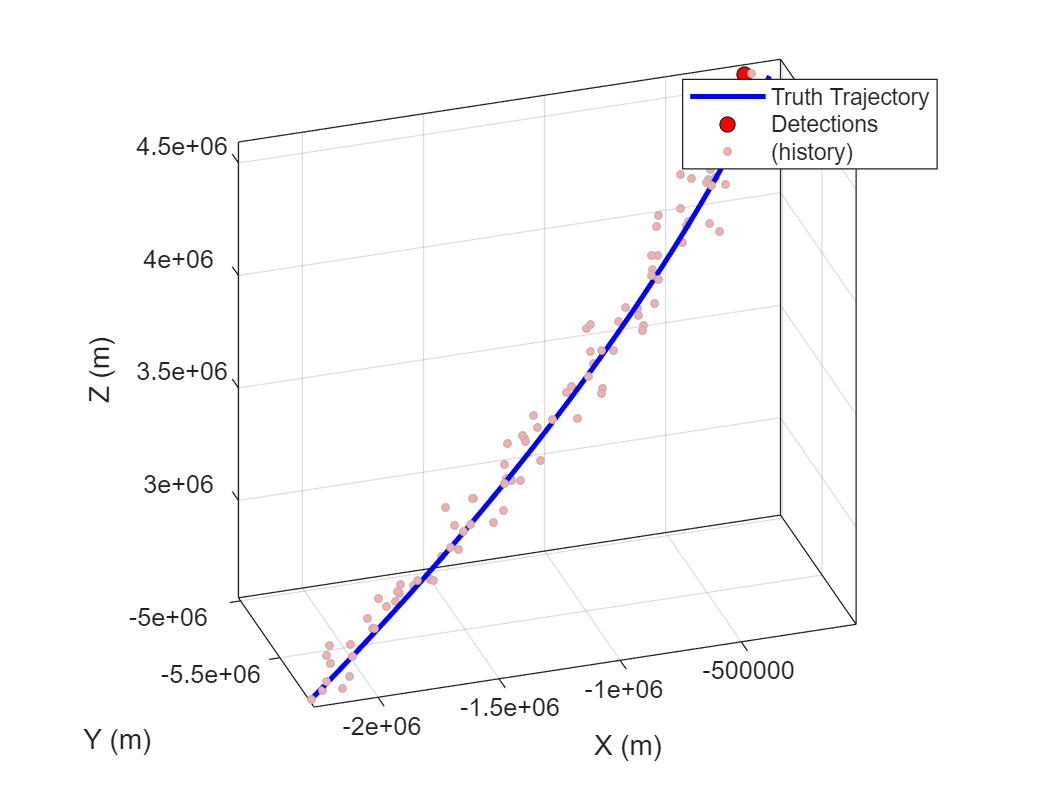

tp.XLimits = xlim(ax);
tp.YLimits = ylim(ax);
tp.ZLimits = zlim(ax);

% Create plotter objects:
%trkPlotter = trackPlotter(tp,'DisplayName','Tracks',ColorizeHistory="on",ConnectHistory="on");
trajPlotter = trajectoryPlotter(tp,'DisplayName','Truth Trajectory','LineWidth',2,'LineStyle','-','Color','b');
detPlotter = detectionPlotter(tp,'HistoryDepth',1e3,'DisplayName','Detections','MarkerFaceColor','r');
plotTrajectory(trajPlotter,{truthPos'})

grid on, box on; legend(gca,'Location','northeast')
view(-18,28)

% Plot Detections in a "as sensor detects target" fashion
for n = 1:length(time)
    % Plot Position of Current Detection iteration 
    plotDetection(detPlotter,detPos(:,n)')
    
    % Pause during loop to watch tracker progress during visualization
    pause(0.1)
end

# **Takeaways:**

We were able to visualize the trajectory of a single piece of space debris using the Sensor Fusion and Tracking tools, which will make it easier for us to test out our tracking algorithms in the future exercises.